clear all


## 1. Lire les donnees avec csvread

data = csvread('profilgravi.dat');
%% Imprimer les dimensions
sprintf('Dimensions des donnees: %d x %d', size(data,1), size(data, 2))

ans = 'Dimensions des donnees: 256 x 2'

## 2. Définir vecteurs gravite et position

posx = data(:,1)'

posx =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


grav = data(:,2)'

grav =    -0.1912    0.2032    0.3051    0.9187    1.1528    1.4470    1.7016    1.5492    2.2373    2.4819    2.3966    2.5046    2.9911    3.1841    3.4351    3.8051    3.9517    3.9234    4.3583    4.8327    5.0082    5.1937    5.0779    5.3646    5.6087    5.6333    6.0438    6.1668    6.5659    6.5550    6.7191    6.8639    7.1291    7.5207    7.3988    7.7323    7.6643    8.1519    8.0443    8.3823    8.5852    8.5278    8.7436    8.9105    8.7557    9.1730    9.0772    9.0371    9.1570    9.1992


## 3. Tracer le signal original

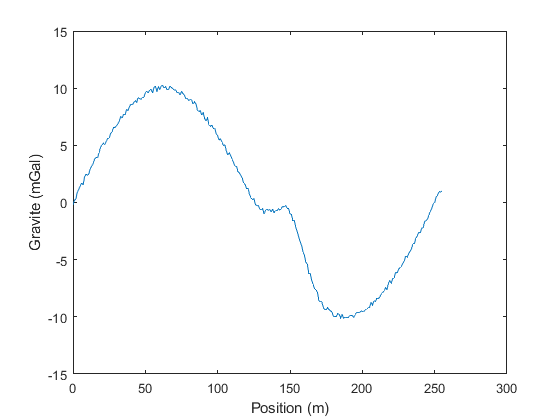

figure()
plot(posx, grav);
xlabel('Position (m)')
ylabel('Gravite (mGal)')

## 4. Certaines definitions

Fs = 1;            % Frequence d'echantillonnage                 
T = 1/Fs;          % Periodre d'echantillonnage  
L = length(data);  % Longueur du signal

## 5. Calculer la transformee directe

tfg = fftshift(fft(grav));
sprintf('Dimensions transformee: %d',length(tfg))

ans = 'Dimensions transformee: 256'

sprintf('Nombres reels?: %d',isreal(tfg))

ans = 'Nombres reels?: 0'

## 6. Définir le vecteur des frequences et visualiser la transformee

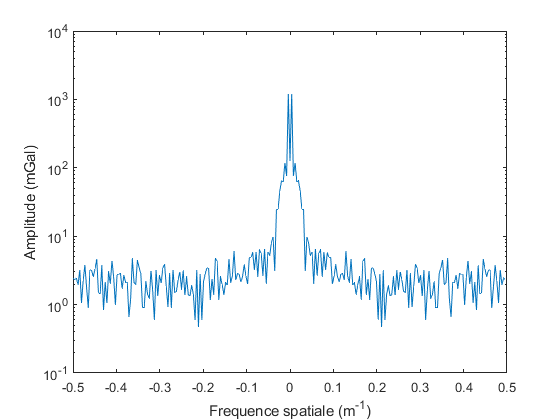

dF = Fs/L;
freq = -Fs/2:dF:Fs/2-dF;
figure()
semilogy(freq, abs(tfg));
xlabel('Frequence spatiale (m^{-1})');
ylabel('Amplitude (mGal)')

## 7. Couper les hautes frequences

cut = abs(freq) > 0.01; % La valeur de coupure depend du signal
tfg(cut) = 0; % Remplacer les valeurs a couper par 0

% Imprimer le masque
cutoff = [freq; cut];
fprintf('%8.3f %8.0f\n', cutoff)

  -0.500        1
  -0.496        1
  -0.492        1
  -0.488        1
  -0.484        1
  -0.480        1
  -0.477        1
  -0.473        1
  -0.469        1
  -0.465        1
  -0.461        1
  -0.457        1
  -0.453        1
  -0.449        1
  -0.445        1
  -0.441        1
  -0.438        1
  -0.434        1
  -0.430        1
  -0.426        1
  -0.422        1
  -0.418        1
  -0.414        1
  -0.410        1
  -0.406        1
  -0.402        1
  -0.398        1
  -0.395        1
  -0.391        1
  -0.387        1
  -0.383        1
  -0.379        1
  -0.375        1
  -0.371        1
  -0.367        1
  -0.363        1
  -0.359        1
  -0.355        1
  -0.352        1
  -0.348        1
  -0.344        1
  -0.340        1
  -0.336        1
  -0.332        1
  -0.328        1
  -0.324        1
  -0.320        1
  -0.316        1
  -0.313        1
  -0.309        1
  -0.305        1
  -0.301        1
  -0.297        1
  -0.293        1
  -0.289        1
  -0.285  

## 8. Faire la transformee inverse du signal coupe

grav_coupe = ifft(ifftshift(tfg));

## 9. Faire un graphique avec les trois signaux

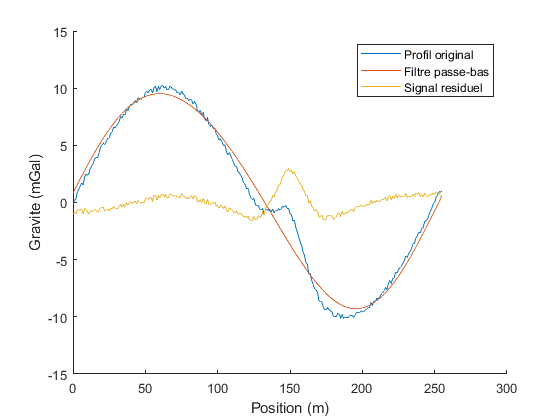

figure()
hold on;
plot(posx, grav);
plot(posx, grav_coupe);
plot(posx, grav-grav_coupe);
legend('Profil original', 'Filtre passe-bas', 'Signal residuel')
xlabel('Position (m)')
ylabel('Gravite (mGal)')